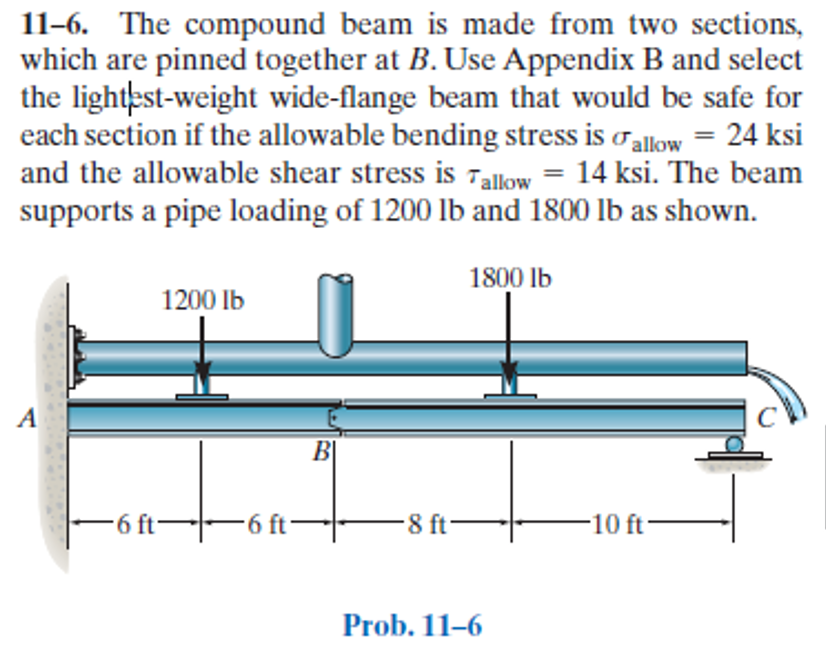

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-6P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-6P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

S = default_struct('reqd', 'design');

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'moment', 'Ma', 0);
b = b.add('concentrated', 'force', -1200*u.lbf, 6*u.ft);
b = b.add('hinge', 'force', 'Hb', 12*u.ft);
b = b.add('concentrated', 'force', -1800*u.lbf, 20*u.ft);
b = b.add('reaction', 'force', 'Rc', 30*u.ft);
b.L = 30*u.ft;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} \frac{100\,x^{2}\,\left(11\,x-288\,\mathrm{ft}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{lbf} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{100\,\left(-5\,x^{3}+180\,x^{2}\,\mathrm{ft}+648\,x\,{\mathrm{ft}}^{2}-1296\,{\mathrm{ft}}^{3}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{lbf} & \text{ if }x\in \left(6\,\mathrm{ft},12\,\mathrm{ft}\right]\\ \frac{500\,\left(x^{3}-36\,x^{2}\,\mathrm{ft}+472\,x\,{\mathrm{ft}}^{2}-6960\,{\mathrm{ft}}^{3}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{lbf} & \text{ if }x\in \left(12\,\mathrm{ft},20\,\mathrm{ft}\right]\\ -\frac{400\,\left(x-30\,\mathrm{ft}\right)\,\left(x^{2}-60\,x\,\mathrm{ft}+310\,{\mathrm{ft}}^{2}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{lbf} & \text{ if }20\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{100\,x\,\left(11\,x-192\,\mathrm{ft}\right)}{\text{E}\,\text{I}}\,\mathrm{lbf} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{100\,\left(-5\,x^{2}+120\,x\,\mathrm{ft}+216\,{\mathrm{ft}}^{2}\right)}{\text{E}\,\text{I}}\,\mathrm{lbf} & \text{ if }x\in \left(6\,\mathrm{ft},12\,\mathrm{ft}\right]\\ \frac{500\,\left(3\,x^{2}-72\,x\,\mathrm{ft}+472\,{\mathrm{ft}}^{2}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{lbf} & \text{ if }x\in \left(12\,\mathrm{ft},20\,\mathrm{ft}\right]\\ -\frac{400\,\left(3\,x^{2}-180\,x\,\mathrm{ft}+2110\,{\mathrm{ft}}^{2}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{lbf} & \text{ if }20\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} 200\,\left(11\,x-96\,\mathrm{ft}\right)\,\mathrm{lbf} & \text{ if }x\leq 6\,\mathrm{ft}\\ 1000\,\left(x-12\,\mathrm{ft}\right)\,\mathrm{lbf} & \text{ if }x\in \left(6\,\mathrm{ft},20\,\mathrm{ft}\right]\\ -800\,\left(x-30\,\mathrm{ft}\right)\,\mathrm{lbf} & \text{ if }20\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} 2200\,\mathrm{lbf} & \text{ if }x\leq 6\,\mathrm{ft}\\ 1000\,\mathrm{lbf} & \text{ if }x\in \left(6\,\mathrm{ft},20\,\mathrm{ft}\right]\\ -800\,\mathrm{lbf} & \text{ if }20\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ma} & 19200\,\mathrm{ft}\,\mathrm{lbf}\\ \mathrm{Ra} & 2200\,\mathrm{lbf}\\ \mathrm{Rc} & 800\,\mathrm{lbf} \end{array}\right)$$

ha

$$ha = \left(\begin{array}{cc} \mathrm{Hb} & -1000\,\mathrm{lbf} \end{array}\right)$$

# shear and moment diagram

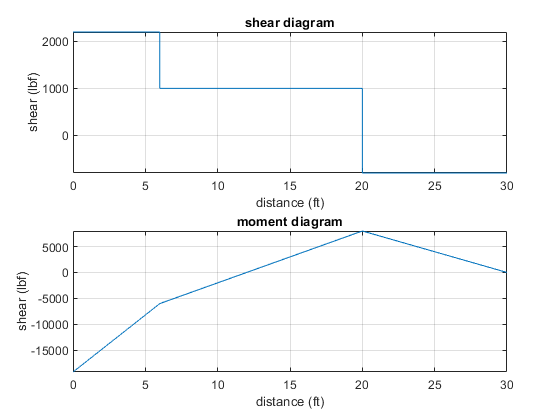

beam.shear_moment(m, v, [0 b.L], {'lbf' 'ft'});

# maximum loads

M_max = abs(m([0; 20]*u.ft))

$$M\_max = \left(\begin{array}{c} 19200\,\mathrm{ft}\,\mathrm{lbf}\\ 8000\,\mathrm{ft}\,\mathrm{lbf} \end{array}\right)$$

V_max = v([0; 15]*u.ft)

$$V\_max = \left(\begin{array}{c} 2200\,\mathrm{lbf}\\ 1000\,\mathrm{lbf} \end{array}\right)$$

# required section modulus

sigma_allow = 24*u.ksi;
S.reqd = rewrite(M_max/sigma_allow, u.in);
S_reqd = vpa(S.reqd) %#ok<NASGU> 

$$S\_reqd = \left(\begin{array}{c} 9.6\,{\mathrm{in}}^{3}\\ 4.0\,{\mathrm{in}}^{3} \end{array}\right)$$

# design section modulus

% ------------------
% - Appendix B table
% ------------------
tbl = beam.appendixB('fps');
Model = tbl.Properties.CustomProperties.Model;
Weight = tbl.Properties.CustomProperties.Weight;
Designation = tbl.Properties.RowNames;
% ---------------------
% - minimum beam weight
% ---------------------
in_range = cell(2,1);
Model_min = in_range;
Weight_min = in_range;
Designation_min = in_range;
min_loc = in_range;
for k = 1:2
  in_range{k} = isAlways(tbl.Sx*u.in^3 >= S.reqd(k));
  Weight_min{k} = symmin(Weight(in_range{k}));
  Model_min{k} = Model(Weight == Weight_min{k} & in_range{k});
  min_loc{k} = isAlways(Model == Model_min{k} & ...
                        Weight == Weight_min{k} & ...
                        in_range{k});
  Designation_min{k} = Designation{min_loc{k}};
end
Designation_min

Designation_min = 2×1 cell array
    {'W10 x 12'}
    {'W6 x 9'  }


% ------------------------
% - design seciton modulus
% ------------------------
S.design = tbl.Sx(Designation_min)*u.in^3;
S_design = vpa(S.design) %#ok<NASGU> 

$$S\_design = \left(\begin{array}{c} 10.9\,{\mathrm{in}}^{3}\\ 5.56\,{\mathrm{in}}^{3} \end{array}\right)$$

# maximum shear stress

tau_allow = 14*u.ksi;
d = tbl.Depth(Designation_min)*u.in;
tw = tbl.Web_Thickness(Designation_min)*u.in;
Aw = d.*tw;
tau_max = rewrite(V_max./Aw, u.ksi);
tau_max_vpa = vpa(tau_max, 3) %#ok<NASGU> 

$$tau\_max\_vpa = \left(\begin{array}{c} 1.17\,\mathrm{ksi}\\ 0.997\,\mathrm{ksi} \end{array}\right)$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear k S_reqd;
clear S_design;
clear tau_max_vpa;